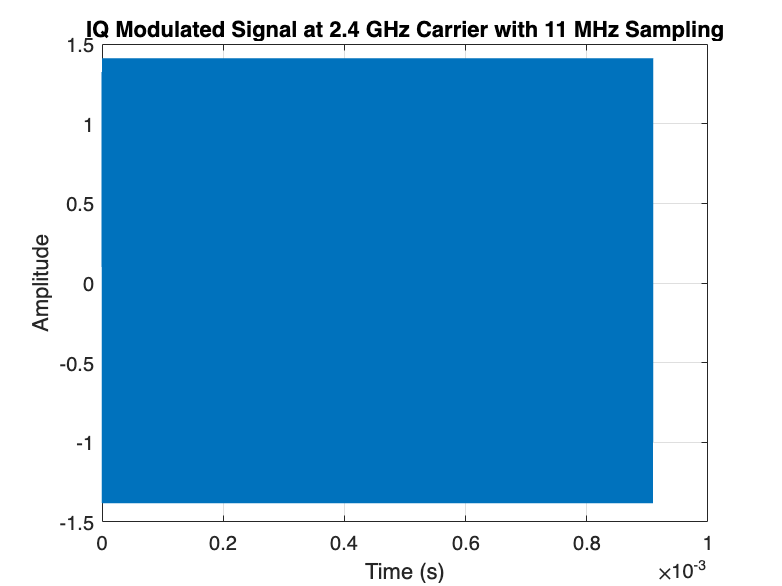

% Parameters
fs = 11e6;  % Sampling frequency (11 MHz)
fc = 2.4e9; % Carrier frequency (2.4 GHz)
t = 0:1/fs:1; % Time vector

% Generate binary data
%data = randi([0, 1], 1, 10000);
%data = [[1,1,1,0,0],randi([1], 1, 9995)];
data = [[1,1,1,0,0],zeros(1,9995)];

% Modulation (BPSK)
symbols = 2 * data - 1;



% Use the same data for both I and Q
I = symbols;
Q = symbols;


% Upconvert to the carrier frequency
t_up = t(1:10000); % Use the first 1000 samples for simplicity
carrier = cos(2*pi*fc*t_up);
carrier_i = sin(2*pi*fc*t_up);

% Modulated signal
iq_modulated = I .* carrier_i + Q .* carrier;

% Plot the modulated signal
figure;
plot(t_up, real(iq_modulated));
title('IQ Modulated Signal at 2.4 GHz Carrier with 11 MHz Sampling');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

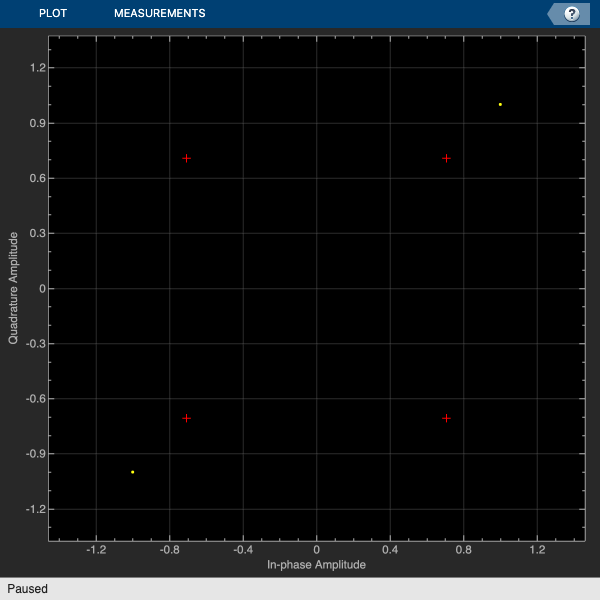

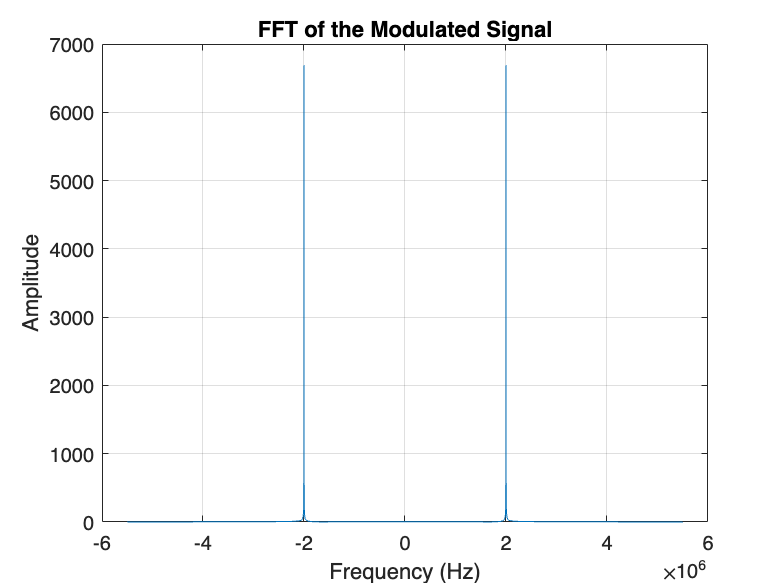


carrier = cos(2*pi);

dbpskmod = comm.DBPSKModulator();
actual = dbpskmod(data.');
backup = actual;

% Loop through each element in the array
for i = 1:numel(actual)
    % Check if the number is positive or negative and modify accordingly
    if actual(i) > 0
        actual(i) = actual(i) + 1i;
    elseif actual(i) < 0
        actual(i) = actual(i) - 1i;
    end
end

constDiagram = comm.ConstellationDiagram;
constDiagram(actual);


dbpskdemod = comm.DBPSKDemodulator();
demod_data = dbpskdemod(iq_modulated.').';
dbpskdemod = comm.DBPSKDemodulator();
demod_data_actual = dbpskdemod(actual).';

disp(data(1,1:10));

     1     1     1     0     0     0     0     0     0     0



disp(demod_data(1,1:10));

     0     0     0     0     0     1     0     0     1     0



disp(demod_data_actual(1,1:10));

     1     1     1     0     0     0     0     0     0     0




%scatterplot(complex(symbols, symbols));
%title('Constellation Diagram');
%constDiagram = comm.ConstellationDiagram;
%constDiagram(iq_modulated.')